# Como resolver EDOs lineares numericamente no MATLAB

## EDO linear e homogênea de 1ª ordem

Vamos resolver o tipo mais simples de EDO: a EDO linear homogênea de 1ª ordem


$$\frac{d}{\textrm{d}x}y\left(x\right)=k\cdot y\left(x\right)$$


Para resolvê-lo numericamente, precisamos não só da equação, mas também das condições iniciais. Para este problema, o estado inicial é o $y(0) =y_0$. Sabemos, então, que a solução analítica dessa EDO será da forma


$$y(x) = y_0 e^{kx}$$


### Passos preliminares

Agora, basta entender o que o MATLAB precisa para resolver a EDO numericamente. Em resumo, o algoritmo que resolve o problema de valor inicial(PVI) precisa:

- De uma função que calcula $dy/dx$ a cada ponto $x$(ou instante de tempo $t$, ou qualquer que seja a variável independente)

- De um intervalo de valores de $x$(ou seja, $x$ indo de 0 a 10, por exemplo)

- Do valor inicial $y_0$

O algoritmo mais usado é o `ode45`, que usa Runge-Kutta de 4ª e 5ª ordem.

`Vamos criar a função dydx:`

**Importante! **Perceba que a constante $k$ aparece como variável local da função. Isso pode ser inconveniente se quisermos mudar o valor de $k$ várias vezes. Uma solução para esse problema é adicionar o parâmetro $k$ na função, e especificar o *function handle* de tal maneira que ele passe esse parâmetro predefinido no momento de chamar a função `ode45`. Assim, temos:

Essa função está no arquivo "`destado.m".`

**Precisamos do parâmetro** $k$** e do valor inicial de** $y$ :

**Agora, vamos criar o intervalo de valores em** $x$. Vamos ir de $x=0$ até $x=10$, para fins deste exemplo:

Agora, podemos usar ode45 para resolver o PVI.

### Usando ODE45 (com código)

A função `ode45` do MATLAB precisa de 3 argumentos(como descrito anteriormente), e seu resultado é um vetor com 2 variáveis $\vec{x}$ e $\vec{y}$ que guardam os valores dos pontos $(x_i,y_i)$ resultantes da solução do PVI. Assim, podemos plotar essa solução num gráfico. O exemplo completo está abaixo:

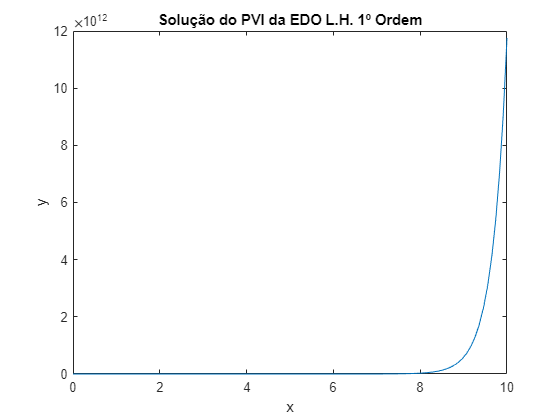

k = 3.0;
y_0 = 1.1;
x_limites = [0 10];
[X, Y] = ode45(@(x, y) destado(x, y, k), x_limites, y_0);
plot(X, Y)
% Adicionar título
title('Solução do PVI da EDO L.H. 1º Ordem')
% Adicionar etiqueta para o eixo y
ylabel('y')
% Adicionar etiqueta para o eixo x
xlabel('x')
hold on

Agora, podemos plotar a solução analítica para comparar:

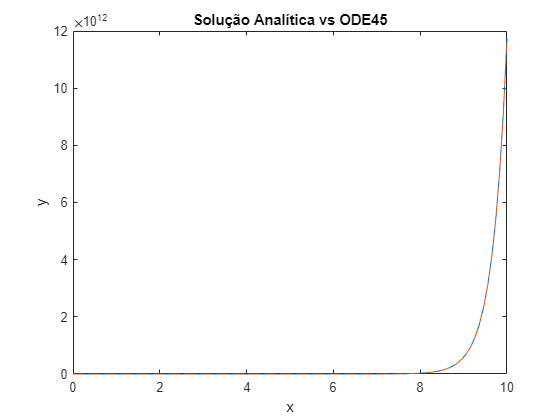

title('Solução Analítica vs ODE45')
Y_analitico = y_0 * exp(k * X);
plot(X, Y_analitico, 'LineStyle','--');
hold off

Perceba que as soluções são exatamente as mesmas, a menos de diferenças pequenas de precisão numérica.

### Solução compacta (código final)

Ao invés de criar uma função "destado.m", neste caso basta criar um *function handle* e jogá-lo direto na expressão do ode45. Assim, o código fica muito mais compacto:

Perceba que o nosso "`dydx`" é justamente a função "`k*y`". Assim, o código final fica bem simples:

k = 3.0;
y_0 = 1.1;
x_limites = [0 10];
[X, Y] = ode45(@(x, y) k*y, x_limites, y_0);
plot(X, Y)
title('Solução do PVI da EDO L.H. 1º Ordem')
ylabel('y')
xlabel('x')

## Solução de EDO linear e homogênea de 2º ordem

### Preliminares

Vamos, agora, resolver o PVI com um sistema massa-mola amortecido de coeficiente $\beta$, massa $m$, constante elástica $k$, posição inicial $x_0$ e velocidade inicial $v_0$.

A EDO em questão é:


$$m \ddot{x} + \beta \dot{x} + kx=0$$


Percebe-se que não dá para separar $dx/dt$ em função apenas de $t, x, k, \beta, m$. Isso acontece pois há o termo de 2ª ordem.

Para resolver o problema, basta indicar uma nova variável $v=\dot{x}$, tal que:


$$\dot{x}=v$$



$$\dot{v}=\ddot{x}=-\frac{\beta v + kx}{m}$$


Assim, o espaço de estados é descrito não por uma única variável $x$, mas pelo vetor $\vec{y} = [x,v]$. Esse passo é importante pois a função ode45 espera que esse seja o formato de entrada em seu algoritmo. Podemos, então pensar na derivada do vetor $\vec{y}$:


$$\frac{d}{\textrm{d}t}\vec{y} =\frac{\textrm{d}}{\textrm{d}t}\left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\dot{y_1 } \\
\dot{y_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
y_2 \\
-\frac{\beta \cdot y_2 +k\cdot y_1 }{m}
\end{array}\right\rbrack$$


A função "destado_massa_mola" fica, então:

Novamente, podemos usar essa função, ou simplesmente usar um *function handle*, para uma notação mais compacta:

### Solução compacta (código final)

Definindo valores de atrito $\mu$, massa $m$, constante elástica $k$, e do estado inicial $\vec{y_0 } =\left\lbrack \begin{array}{c}
x_0 \\
v_0 
\end{array}\right\rbrack$, temos:

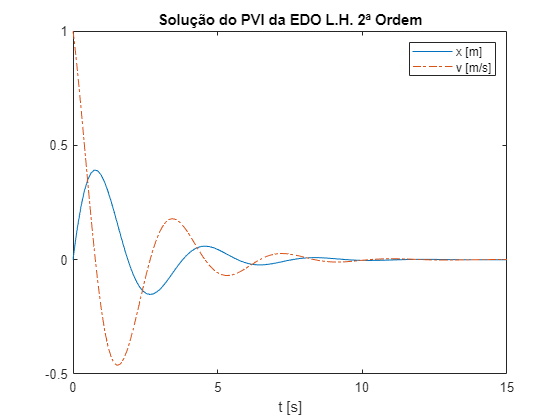

% Definir parâmetros
k = 3.0;
beta = 1.0;
m = 1.0;
y_0 = [0.0 1.0];
t_limites = [0 15];
% Definir função "derivada do estado"
dydt = @(t, y) [y(2); -(beta*y(2) + k*y(1))/m];
% Resolver PVI
[t, y] = ode45(dydt, t_limites, y_0);
% Fazer plot
plot(t,y(:,1),'-')
hold on
plot(t,y(:,2),'-.')
title('Solução do PVI da EDO L.H. 2ª Ordem')
legend('x [m]','v [m/s]')
xlabel('t [s]')
hold off

## Solução de EDO linear e homogênea de 2º ordem forçada

### Preliminares

Voltando ao problema anterior, vamos introduzir uma força que varia com o tempo $f(t)$, tal que a EDO fique:


$$m \ddot{x} + \beta \dot{x} + kx=f(t)$$


Simplificando para um sistema de EDO's, obtemos:


$$\dot{x}=v$$



$$\dot{v}=\ddot{x}=f(t)-\frac{\beta v + kx}{m}$$


Vamos usar $f(t)$ como uma onda quadrada, isto é, aplica-se uma força constante de magnitude $F$por um tempo $T$ em $+\hat{x}$, depois alterna-se para aplicar a mesma magnitude em $-\hat{x}$.

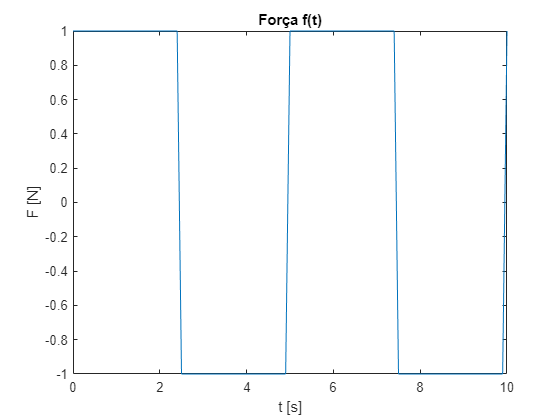

f_opts = @(t, F, T) F*square(pi*t/T);
F = 1.0;
T = 2.5;
f = @(t) f_opts(t, F, T);
t = 0:0.1:10;
plot(t, f(t))
title('Força f(t)')
xlabel('t [s]')
ylabel('F [N]')

### Solução compacta (código final)

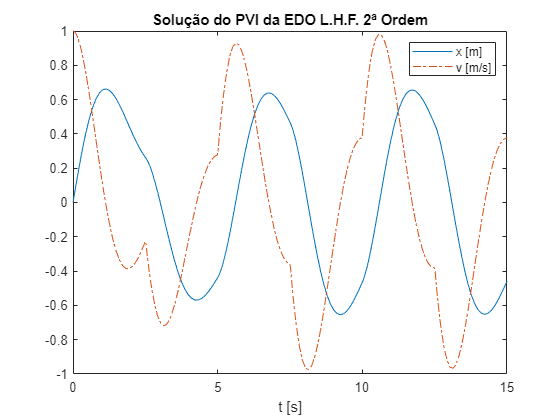

% Definir parâmetros
k = 3.0;
beta = 1.0;
m = 1.0;
y_0 = [0.0 1.0];
t_limites = [0 15];
% Definir função "derivada do estado"
dydt = @(t, y) [y(2); f(t)-(beta*y(2) + k*y(1))/m];
% Resolver PVI
[t, y] = ode45(dydt, t_limites, y_0);
% Fazer plot
plot(t,y(:,1),'-')
hold on
plot(t,y(:,2),'-.')
title('Solução do PVI da EDO L.H.F. 2ª Ordem')
legend('x [m]','v [m/s]')
xlabel('t [s]')
hold off